clear all;
file = "lab1/data/data_04-Mar-2025_10.mat";

load(file,"data")

fs=500

fs = 500

ts = 1/fs

ts = 0.0020

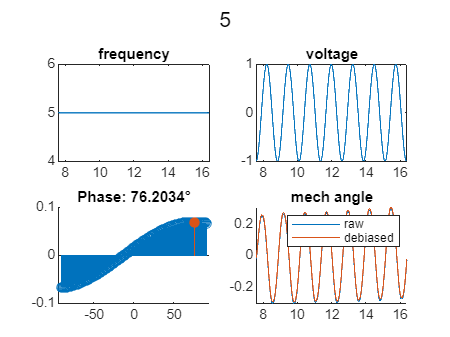

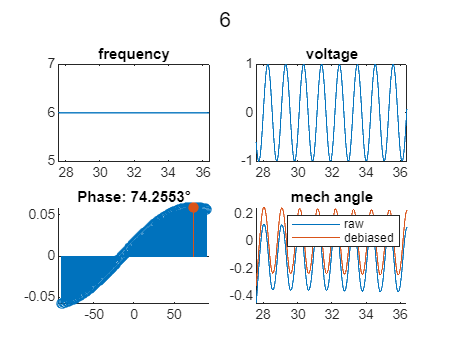

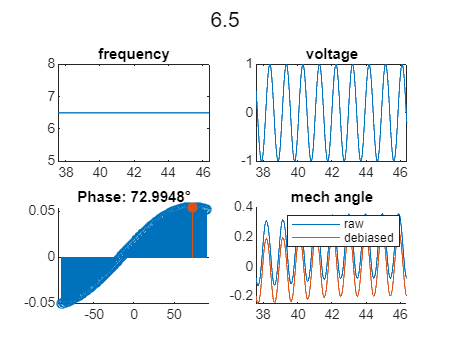

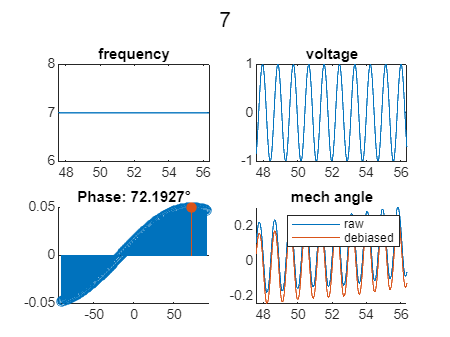

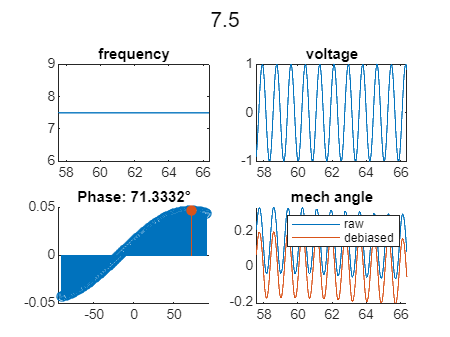

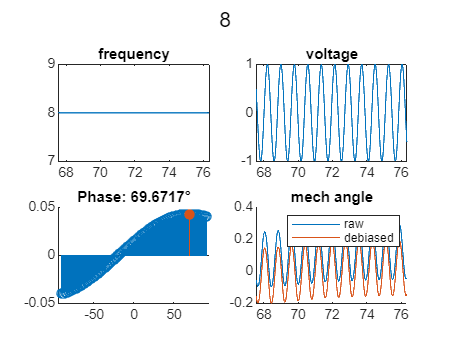

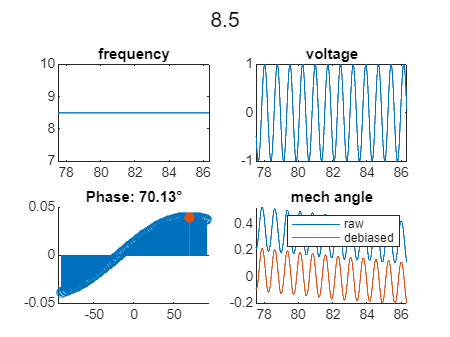

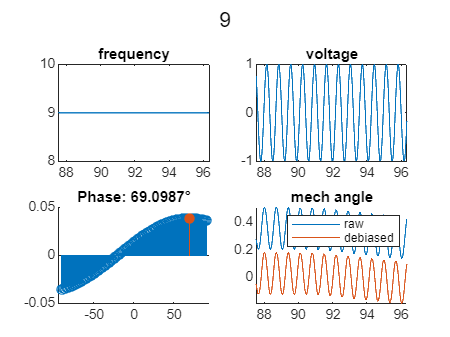



omegas = [0 , 0 , 0]';
omegas_proper = [];
t = data(1,:);
y = data(2,:)*pi/2048;
u = data(4,:);
w = data(6,:);

ph = [];
wrong_exp = [ 0 5.5 13 17.5 18 20];

%find all the frequencies

for i = 1:10:size(t,2)-600
    if w(i+600) == w(i) % we are not in a transition
        if w(i) ~= omegas(1,end)
          omegas(1, end+1 )  = w(i);
           omegas(2, end) = t(i);
           omegas(3, end-1) = t(i-600);
          if  w(i) == 20
            omegas(3, end) = floor(397000/500);
          end
        end
    end
end    


for i =1:size(omegas,2)
omega = omegas(1,i);
k = find(wrong_exp==omega);
if size(k,2)==0
    
    omegas_proper(end+1)=omega;
    t_start = omegas(2,i);
    t_end = omegas(3,i);
    
    Tfocus = t_end -t_start;

    idx_start = time2index(t_start)+1;
    idx_end = time2index(t_end);
    om = w(idx_start:idx_end);
    u_focus = u(idx_start:idx_end);
    y_focus = y(idx_start:idx_end);
    t_steady = t(idx_start:idx_end);
    % analysis
    
    
    T = 2*pi/omega;
    Fv = 1/T;
    max_samples_per_period = ceil(T/ts);

    angular_resolution = 360/max_samples_per_period;
    maxlag_n = ceil(max_samples_per_period/4);
    %% debias
    Integ = trapz(t_steady,y_focus);
    b = Integ/Tfocus;
    y_deb = y_focus - b;
    
    %% cross corr
    [c,lags] = xcorr(u_focus,y_deb,maxlag_n,'biased' );
    c = c/2;

     [c_max, cmaxid] = max(c);
    focus_window = max_samples_per_period*2;
    
    maxlag_time = (2*maxlag_n + 1) * ts;
    lags_time = lags * ts;
    lags_rad = lags_time * 2 * pi / T;

    Phase = lags_rad(cmaxid);

    ph(end+1) = Phase;

    figure

    subplot(2,2,1)
    plot(t_steady,om)
    title("frequency")


    subplot(2,2,2)
    plot(t_steady,u_focus)
    title("voltage")

    subplot(2,2,4)
    hold on
    plot(t_steady,y_focus)
    plot(t_steady,y_deb)
    legend("raw","debiased")
    title("mech angle")
    hold off

     subplot(2,2,3)
    title("Phase: " + rad2deg(Phase) + "°")
    hold on
    stem(lags*angular_resolution,c)
    stem(rad2deg(Phase),c_max,"filled")
    hold off
    sgtitle(omega)
end    
end


guess_crofreq = 25;
ideal = 90-rad2deg(atan(omegas_proper/guess_crofreq))

ideal =    78.6901   76.5043   75.4258   74.3578   73.3008   72.2553   71.2220   70.2011   69.1932   68.1986   67.2176   66.2505   65.2976   64.3590   63.4349   61.6310   60.7512   59.8863   59.0362   58.2011   57.3808   56.5752   55.7843   53.4986   52.7652   52.0458


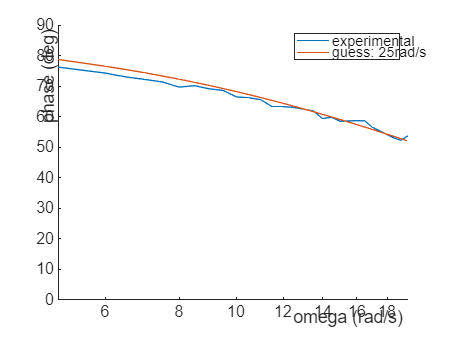

figure
hold on
plot(omegas_proper,rad2deg(ph))
plot(omegas_proper,ideal)
hold off
legend(["experimental","guess: "+guess_crofreq+"rad/s"])
xscale("log")
ylim([0 90])
xlabel("omega (rad/s)")
ylabel("phase (deg)")
title("Bode diagram of phase")

function idx = time2index(time)
    idx = ceil(time/0.002);
end



